%Code : Anne-Lise Marais
%Preprocessing : Marie Anquetil w/ Netstation EGI
%Subject 2
%This code plots the average brain (EEG) responses to an Attention Network Task (ANT)-like task of a child (anonymous)
%4 conditions are plotted : congruent, incongruent, vald,  invalid
%3 brain regions : prefrontal, frontal, parietal
%Variables in the workspace are segments from the EEG data

%Create a 3D matrix (x = electrodes (129), y = eeg data (1300) et z = condition (n)) for all condition using cat function on dimension z
Congruent=cat(3, congruent_Segment_002, congruent_Segment_003, congruent_Segment_004, congruent_Segment_005, congruent_Segment_006, congruent_Segment_007, congruent_Segment_008, congruent_Segment_009, congruent_Segment_010, congruent_Segment_011, congruent_Segment_012, congruent_Segment_013, congruent_Segment_014, congruent_Segment_015, congruent_Segment_017, congruent_Segment_018, congruent_Segment_019, congruent_Segment_020, congruent_Segment_021, congruent_Segment_022, congruent_Segment_023, congruent_Segment_024, congruent_Segment_025, congruent_Segment_026, congruent_Segment_027, congruent_Segment_028, congruent_Segment_029, congruent_Segment_030, congruent_Segment_031, congruent_Segment_033, congruent_Segment_034, congruent_Segment_036, congruent_Segment_037, congruent_Segment_038, congruent_Segment_039, congruent_Segment_040, congruent_Segment_041, congruent_Segment_042, congruent_Segment_043, congruent_Segment_046, congruent_Segment_047, congruent_Segment_048, congruent_Segment_049, congruent_Segment_050, congruent_Segment_051, congruent_Segment_052, congruent_Segment_053, congruent_Segment_054, congruent_Segment_055, congruent_Segment_056, congruent_Segment_057, congruent_Segment_059, congruent_Segment_060, congruent_Segment_061, congruent_Segment_063, congruent_Segment_064, congruent_Segment_065, congruent_Segment_066, congruent_Segment_067, congruent_Segment_069, congruent_Segment_071, congruent_Segment_072);
Incongruent=cat(3,incongruent_Segment_001,incongruent_Segment_002,incongruent_Segment_003,incongruent_Segment_004,incongruent_Segment_005,incongruent_Segment_006,incongruent_Segment_007,incongruent_Segment_008,incongruent_Segment_010,incongruent_Segment_013,incongruent_Segment_014,incongruent_Segment_015,incongruent_Segment_017,incongruent_Segment_018,incongruent_Segment_019,incongruent_Segment_020,incongruent_Segment_021,incongruent_Segment_022,incongruent_Segment_023,incongruent_Segment_024,incongruent_Segment_025,incongruent_Segment_026,incongruent_Segment_027,incongruent_Segment_028,incongruent_Segment_030,incongruent_Segment_031,incongruent_Segment_032,incongruent_Segment_034,incongruent_Segment_035,incongruent_Segment_036,incongruent_Segment_038,incongruent_Segment_042,incongruent_Segment_043,incongruent_Segment_044,incongruent_Segment_047,incongruent_Segment_049,incongruent_Segment_050, incongruent_Segment_051,incongruent_Segment_052,incongruent_Segment_053,incongruent_Segment_055,incongruent_Segment_057,incongruent_Segment_059,incongruent_Segment_061,incongruent_Segment_062,incongruent_Segment_064,incongruent_Segment_065,incongruent_Segment_067,incongruent_Segment_068,incongruent_Segment_070);
Valid=cat(3,valid_Segment_002,valid_Segment_003,valid_Segment_004,valid_Segment_005,valid_Segment_006,valid_Segment_007,valid_Segment_008,valid_Segment_009,valid_Segment_011,valid_Segment_012,valid_Segment_013,valid_Segment_014,valid_Segment_015,valid_Segment_017,valid_Segment_018,valid_Segment_019,valid_Segment_020,valid_Segment_021,valid_Segment_023,valid_Segment_024,valid_Segment_025,valid_Segment_026,valid_Segment_027,valid_Segment_028,valid_Segment_029,valid_Segment_031,valid_Segment_033,valid_Segment_038,valid_Segment_039,valid_Segment_041,valid_Segment_042,valid_Segment_043,valid_Segment_046,valid_Segment_047,valid_Segment_048,valid_Segment_049,valid_Segment_050,valid_Segment_052,valid_Segment_053,valid_Segment_054,valid_Segment_055,valid_Segment_056,valid_Segment_059,valid_Segment_060,valid_Segment_061,valid_Segment_062,valid_Segment_064,valid_Segment_065,valid_Segment_067,valid_Segment_069,valid_Segment_071);
Invalid=cat(3,invalid_Segment_001,invalid_Segment_002,invalid_Segment_003,invalid_Segment_004,invalid_Segment_005,invalid_Segment_006,invalid_Segment_007,invalid_Segment_011,invalid_Segment_012,invalid_Segment_013,invalid_Segment_014,invalid_Segment_017,invalid_Segment_018,invalid_Segment_019,invalid_Segment_020,invalid_Segment_021,invalid_Segment_022,invalid_Segment_023,invalid_Segment_024,invalid_Segment_025,invalid_Segment_026,invalid_Segment_027,invalid_Segment_028,invalid_Segment_029,invalid_Segment_030,invalid_Segment_031,invalid_Segment_032,invalid_Segment_033,invalid_Segment_034,invalid_Segment_035,invalid_Segment_036,invalid_Segment_037,invalid_Segment_038,invalid_Segment_039,invalid_Segment_042,invalid_Segment_043,invalid_Segment_044,invalid_Segment_046,invalid_Segment_047,invalid_Segment_048,invalid_Segment_049,invalid_Segment_050,invalid_Segment_051,invalid_Segment_052,invalid_Segment_053,invalid_Segment_054,invalid_Segment_056,invalid_Segment_058,invalid_Segment_059,invalid_Segment_062,invalid_Segment_062,invalid_Segment_065,invalid_Segment_066,invalid_Segment_067,invalid_Segment_068,invalid_Segment_072);

%Mean matrix on dimension z (mean segments to obtain grand average per conditon) for each condition
Mean_Congruent=mean(Congruent,3);
Mean_Incongruent=mean(Incongruent,3);
Mean_Valid=mean(Valid,3);
Mean_Invalid=mean(Invalid,3);

%Mean electrodes of regions of interest (prefrontal = 11, 24, 124; frontal = 6, 29, 111; parietal = 52, 62, 92) for each condition
%congruent
Mean_Congruent_prefrtl=mean(Mean_Congruent([11, 24, 124], :));
Mean_Congruent_frtl=mean(Mean_Congruent([6, 29, 111], :));
Mean_Congruent_prtl=mean(Mean_Congruent([52, 62, 92], :));
%incongruent
Mean_Incongruent_prefrtl=mean(Mean_Incongruent([11, 24, 124], :));
Mean_Incongruent_frtl=mean(Mean_Incongruent([6, 29, 111], :));
Mean_Incongruent_prtl=mean(Mean_Incongruent([52, 62, 92], :));
%valid
Mean_Valid_prefrtl=mean(Mean_Valid([11, 24, 124], :));
Mean_Valid_frtl=mean(Mean_Valid([6, 29, 111], :));
Mean_Valid_prtl=mean(Mean_Valid([52, 62, 92], :));
%invalid
Mean_Invalid_prefrtl=mean(Mean_Invalid([11, 24, 124], :));
Mean_Invalid_frtl=mean(Mean_Invalid([6, 29, 111], :));
Mean_Invalid_prtl=mean(Mean_Invalid([52, 62, 92], :));

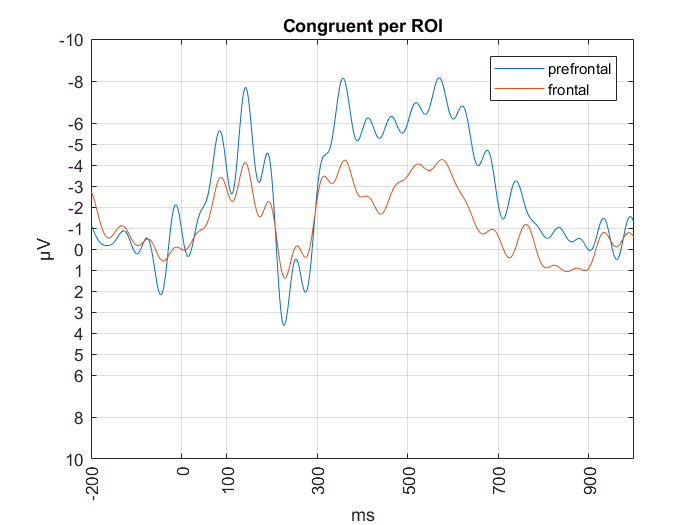

%Plot frontal and prefrontal ROI per condition
%congruent
plot(Mean_Congruent_prefrtl)
hold on
plot(Mean_Congruent_frtl)
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Congruent per ROI'
legend 'prefrontal' 'frontal'

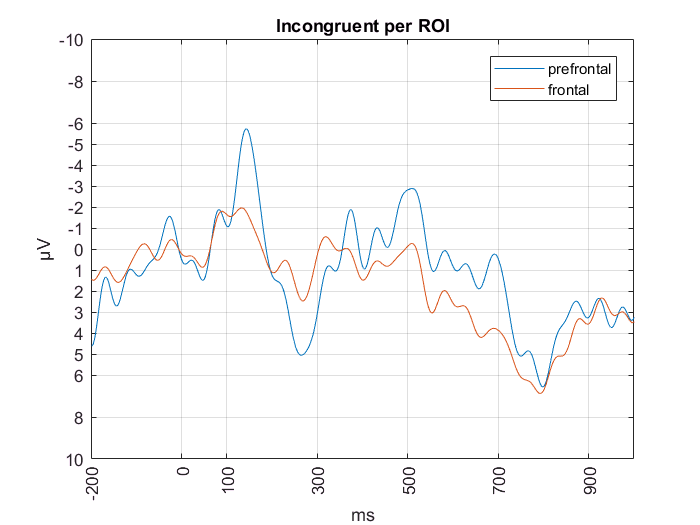

%incongruent
plot(Mean_Incongruent_prefrtl)
hold on
plot(Mean_Incongruent_frtl)
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Incongruent per ROI'
legend 'prefrontal' 'frontal' 

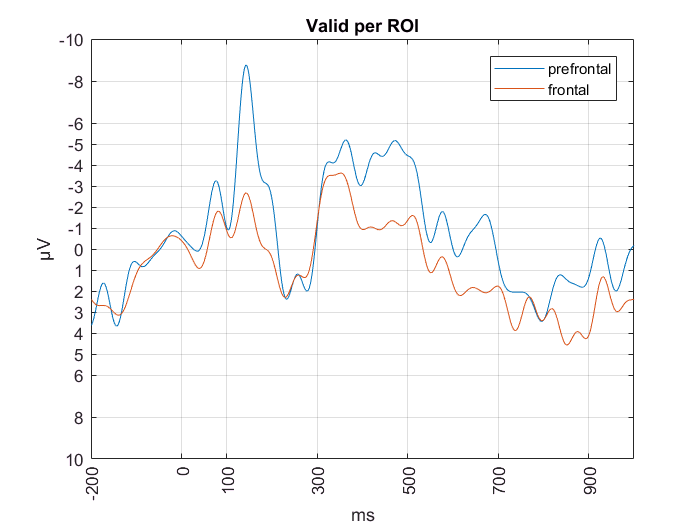

%valid
plot(Mean_Valid_prefrtl)
hold on
plot(Mean_Valid_frtl)
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Valid per ROI'
legend 'prefrontal' 'frontal' 

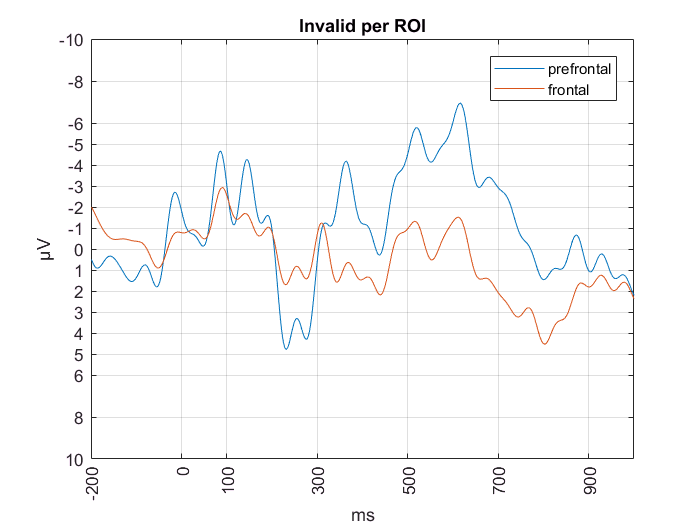

%invalid
plot(Mean_Invalid_prefrtl)
hold on
plot(Mean_Invalid_frtl)
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Invalid per ROI'
legend 'prefrontal' 'frontal' 

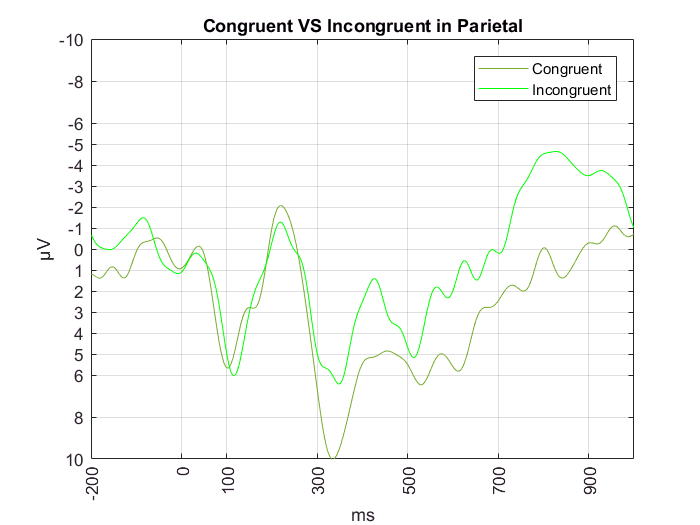

%Plot Incongruent vs congruent in ROI
%Parietal
plot(Mean_Congruent_prtl, 'color', [0.4660, 0.6740, 0.1880])
hold on
plot(Mean_Incongruent_prtl, 'g')
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Congruent VS Incongruent in Parietal'
legend 'Congruent' 'Incongruent'

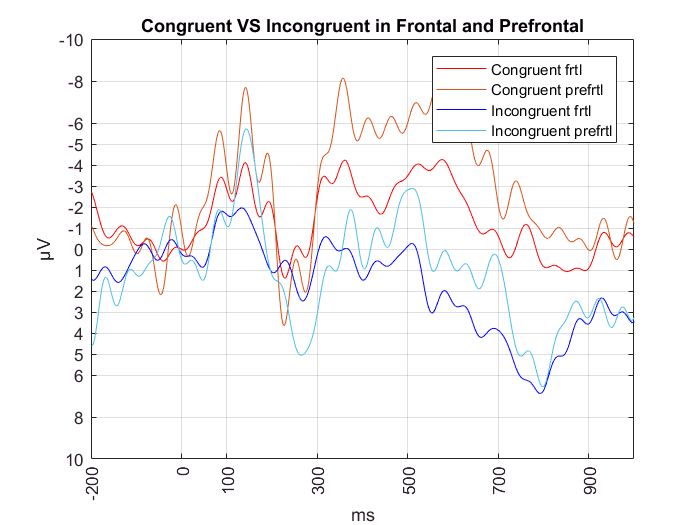

%frontal and prefrontal
plot(Mean_Congruent_frtl, 'r')
hold on
plot(Mean_Congruent_prefrtl, 'color',[0.8500 0.3250 0.0980])
plot(Mean_Incongruent_frtl, 'b')
plot(Mean_Incongruent_prefrtl, 'color', [0.3010, 0.7450, 0.9330])
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Congruent VS Incongruent in Frontal and Prefrontal'
legend 'Congruent frtl' 'Congruent prefrtl' 'Incongruent frtl' 'Incongruent prefrtl'

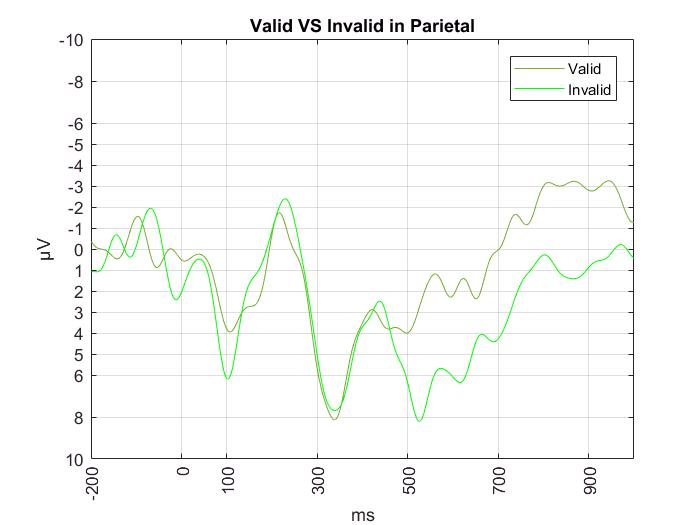

%Plot Valid VS Invalid in ROI
%Parietal
plot(Mean_Valid_prtl, 'color', [0.4660, 0.6740, 0.1880])
hold on
plot(Mean_Invalid_prtl, 'g')
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Valid VS Invalid in Parietal'
legend 'Valid' 'Invalid'

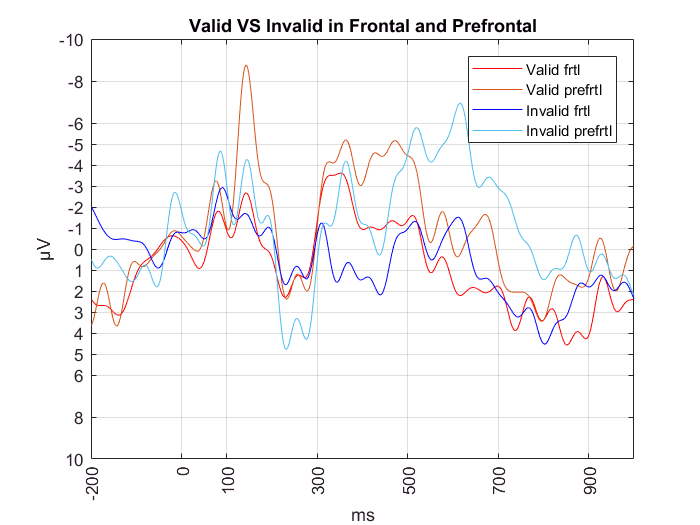

%frontal and prefrontal
plot(Mean_Valid_frtl, 'r')
hold on
plot(Mean_Valid_prefrtl, 'color',[0.8500 0.3250 0.0980])
plot(Mean_Invalid_frtl, 'b')
plot(Mean_Invalid_prefrtl, 'color', [0.3010, 0.7450, 0.9330])
hold off
set(gca,'YDir','reverse')
ylim([-10,10])
yticks([-10 -8 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 8 10])
ylabel('µV')
xlim([0,1200])
xticks([0 200 300 500 700 900 1100])
xticklabels({'-200','0','100','300','500', '700', '900'})
xlabel('ms')
xtickangle(90)
grid on
title 'Valid VS Invalid in Frontal and Prefrontal'
legend 'Valid frtl' 'Valid prefrtl' 'Invalid frtl' 'Invalid prefrtl'